# Post processing

## Read futek data

% should add out folder to matlab path
fds = fileDatastore('futek_data/experiment_*.txt', 'ReadFcn', @importdata);
fullFileNames = fds.Files;
% [pathstr, name, ext] = fileparts(fullFileNames{1})
numFiles = length(fullFileNames);
% Loop over all files reading them in and plotting them.
futek_data = cell(numFiles,2);
for k = 1 : numFiles

    fprintf('Now reading file %s\n', fullFileNames{k});
    A = import_futek_data(fullFileNames{k});
    if isempty(A) == false
        futek_data{k,1} = A;
        temp = strsplit(fullFileNames{k},"/");
        futek_data{k,2} = temp{end};
    end
end

## Read velostat data

fds = fileDatastore('velostat_data/experiment_*.txt', 'ReadFcn', @importdata);
fullFileNames = fds.Files;
% [pathstr, name, ext] = fileparts(fullFileNames{1})
numFiles = length(fullFileNames);
% Loop over all files reading them in and plotting them.
velostat_data = cell(numFiles,2);
for k = 1 : numFiles

    fprintf('Now reading file %s\n', fullFileNames{k});
    A = import_velostat_data(fullFileNames{k});
    if isempty(A) == false
        velostat_data{k,1} = A;
        temp = strsplit(fullFileNames{k},"/");
        velostat_data{k,2} = temp{end};
    end
end


## Calibrate velostat

fds = fileDatastore('velostat_data_for_calibration_new_1_good/experiment_*.txt', 'ReadFcn', @importdata);
fullFileNames = fds.Files;
% [pathstr, name, ext] = fileparts(fullFileNames{1})
numFiles = length(fullFileNames);
% Loop over all files reading them in and plotting them.
velostat_data_calibrated = cell(numFiles,2);
for k = 1 : numFiles

    fprintf('Now reading file %s\n', fullFileNames{k});
    A = calibrate_velostat_data(fullFileNames{k});
    if isempty(A) == false
        velostat_data_calibrated{k,1} = A;
        temp = strsplit(fullFileNames{k},"/");
        velostat_data_calibrated{k,2} = temp{end};
    end
end

Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/velostat_data_for_calibration_new_1_good/experiment_0.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/velostat_data_for_calibration_new_1_good/experiment_1.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/velostat_data_for_calibration_new_1_good/experiment_10.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/velostat_data_for_calibration_new_1_good/experiment_11.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/velostat_data_for_calibration_new_1_good/experiment_12.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/velostat_data_for_calibration_new_1_good/experiment_13.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/velostat_data_for_calibration_new_1_good/experiment_14.txt
Now reading file /home/lupasic/Programs/pyt

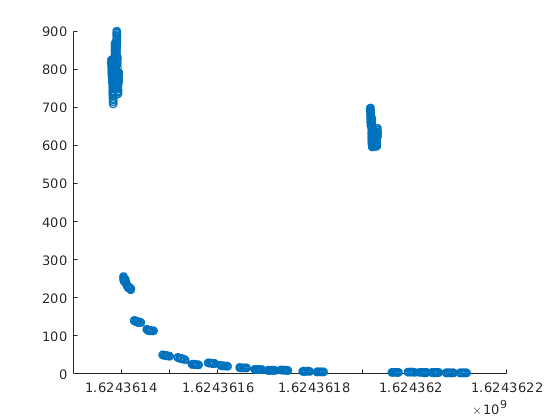


% Concatenate all data for boxplot
calibrate = cat(1,velostat_data_calibrated{:,1});
tim = cell2mat(calibrate(:,2));
vel = cell2mat(calibrate(:,1));
real = cell2mat(calibrate(:,3));

scatter(tim,real)
figure
scatter(tim,vel)

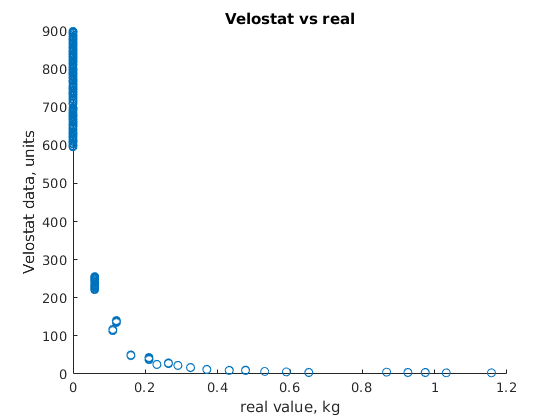

figure 
cur_plot = scatter(real,vel);
title("Velostat vs real");
xlabel("real value, kg");
ylabel("Velostat data, units");

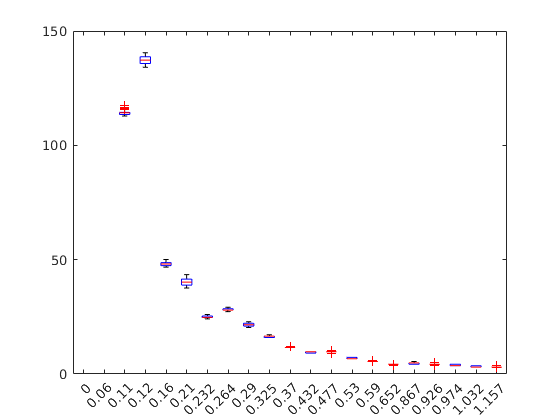

figure
boxplot(vel,real)
ylim([0 150])

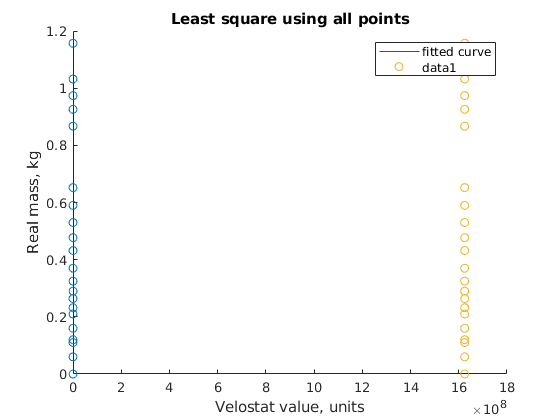

fitpoints1 =      General model Exp2:
     fitpoints1(x) = a*exp(b*x) + c*exp(d*x)
     Coefficients (with 95% confidence bounds):
       a =      0.3014  (0.1987, 0.4041)
       b =   -0.008011  (-0.01477, -0.001247)
       c =       1.648  (1.281, 2.014)
       d =     -0.2337  (-0.3073, -0.1601)

gof1 = struct with fields:
           sse: 0.0584
       rsquare: 0.9778
           dfe: 18
    adjrsquare: 0.9741
          rmse: 0.0570


figure

median_real_vel = zeros(numFiles,2);
for k = 1 : numFiles
    temp = velostat_data_calibrated{k,1};
    median_real_vel(k,1) = median(cell2mat(temp(:,1)));
    median_real_vel(k,2) = median(cell2mat(temp(:,3)));
end
figure
[fitpoints1, gof1] = fit(median_real_vel(:,1),median_real_vel(:,2),'exp2','Robust','on')

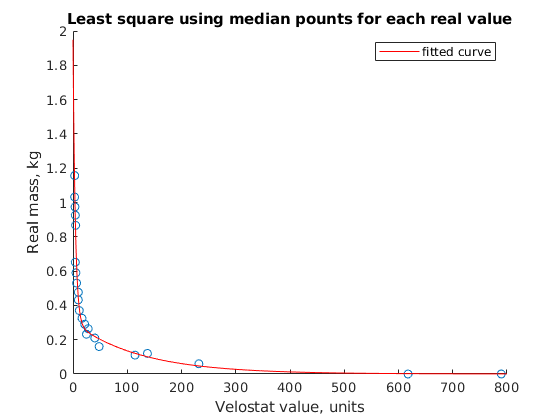

scatter(median_real_vel(:,1),median_real_vel(:,2))
hold on
plot(fitpoints1)
title("Least square using median pounts for each real value")
ylabel("Real mass, kg")
xlabel("Velostat value, units")


figure
[fitpoints2, gof2] = fit(vel,real,'exp1','Robust','on')

fitpoints2 =      General model Exp1:
     fitpoints2(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =   2.647e-31  (-1.272e-17, 1.272e-17)
       b =     0.04617  (-5.455e+10, 5.455e+10)

gof2 = struct with fields:
           sse: 1.7295e+04
       rsquare: -2.0640
           dfe: 47153
    adjrsquare: -2.0640
          rmse: 0.6056


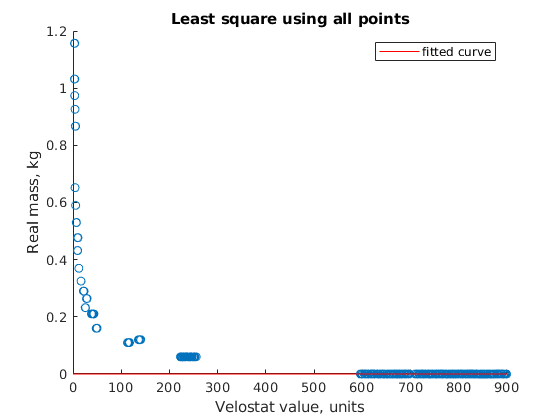

scatter(vel,real)
hold on
plot(fitpoints2)
title("Least square using all points")
ylabel("Real mass, kg")
xlabel("Velostat value, units")

% autocorr(vel)

corr_coeff = corr(median_real_vel(:,1),median_real_vel(:,2))

corr_coeff = -0.5386

cov_coeff = cov(median_real_vel(:,1),median_real_vel(:,2))

cov_coeff = 	1.0e+04 *

    4.2356   -0.0039
   -0.0039    0.0000


## Exp 0 

num = (1:2);

exp0_futek_data = futek_data(num,:);

exp0_velostat_data = velostat_data(num,:);

exp0_title_name = "Experiment 0, testing: ";

needed_max = quantile(cell2mat(exp0_velostat_data{2,1}(:,1)),0.8);

temp_array = cell2mat(exp0_velostat_data{2,1}(:,:));

temp_array(temp_array(:,1)>needed_max,:) = [];

exp0_velostat_data{2,1} = mat2cell(temp_array,[size(temp_array,1),2]);

exp0_sensor_names = ["10 min","pikes"];

exp0_rmse = common_postproc_plots(exp0_futek_data,exp0_velostat_data, exp0_title_name, exp0_sensor_names);

## Experiment 1, repitability

num = (7:11);
exp1_futek_data = futek_data(num,:);
exp1_velostat_data = velostat_data_calibrated(num,:);
exp1_title_name = "Experiment 1, data repitability: ";
exp1_sensor_names = (1:5);
exp1_rmse = common_postproc_plots(exp1_futek_data,exp1_velostat_data, exp1_title_name, exp1_sensor_names);


## Experiment 2, pressure vs Force

num = (5:6);
exp2_futek_data = futek_data(num,:);
exp2_velostat_data = velostat_data_calibrated(num,:);
exp2_title_name = "Experiment 2, pressure vs force: ";
exp2_sensor_names = ["big", "small"];
exp2_rmse = common_postproc_plots(exp2_futek_data,exp2_velostat_data, exp2_title_name, exp2_sensor_names);


## Experiment 3, sensor force map

num = (2:3);
exp3_futek_data = futek_data((num),:);
exp3_velostat_data = velostat_data_calibrated((num),:);
exp3_title_name = "Experiment 3, sensor force map: ";
exp3_sensor_names = ["big", "small"];
exp3_rmse = common_postproc_plots(exp3_futek_data,exp3_velostat_data, exp3_title_name, exp3_sensor_names);

figure
Zb = [[137,330,413,551];[275,413,413,275];[0,275,235,0];[0,149,206,0]];
Zs = [[235,235,275,235];[126,183,149,164];[149,183,149,126];[96,91,126,126]];
bar3(Zb);
title("Experiment 3, sensor big");
xlabel("sensor sector along x, unit");
ylabel("sensor sector along y, units");
zlabel("Max Force, unit")
figure
bar3(Zs);
title("Experiment 3, sensor small");
xlabel("sensor sector along x, unit");
ylabel("sensor sector along y, units");
zlabel("Max Force, unit")

disp("TODO statistics")

## Experiment 4, leg load simulation (rolling rolls)

num = (4);
exp4_futek_data = futek_data(num,:);
exp4_velostat_data = velostat_data_calibrated(num,:);
exp4_title_name = "Experiment 4, leg load simulation: ";
exp4_sensor_names = ["rolling"];
exp4_rmse = common_postproc_plots(exp4_futek_data,exp4_velostat_data, exp4_title_name, exp4_sensor_names);
